# Decryption

clc;
clear;
close all;

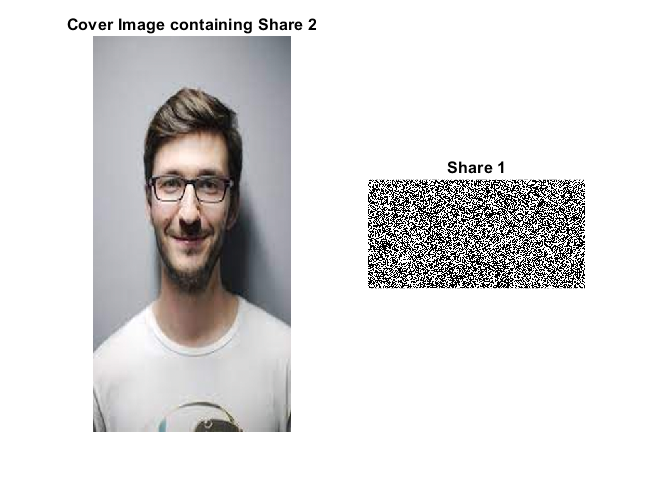

% Read the images
face = imread('face.tif');
share1 = imread('Share1.tif');
share1 = imbinarize(share1);

figure;subplot(121);imshow(face);title('Cover Image containing Share 2'); 
       subplot(122);imshow(share1);title('Share 1');

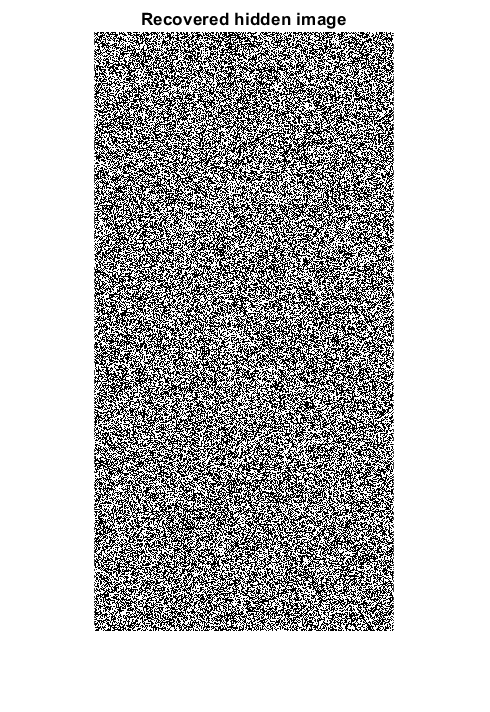

employee = 123456789;
tic;
x =  rem(employee,3)+1;
% inverse watermarking

layer = face(:,:,x);
a=mod(layer,2);
b=zeros(600,300);
for x=1:600
    for y=1:300
        if(a(x,y)==1)
            b(x,y)=255;
        end
    end
end
recImg=imbinarize(b);
t1 = toc;
figure
imshow(recImg); % hidden image
title('Recovered hidden image')

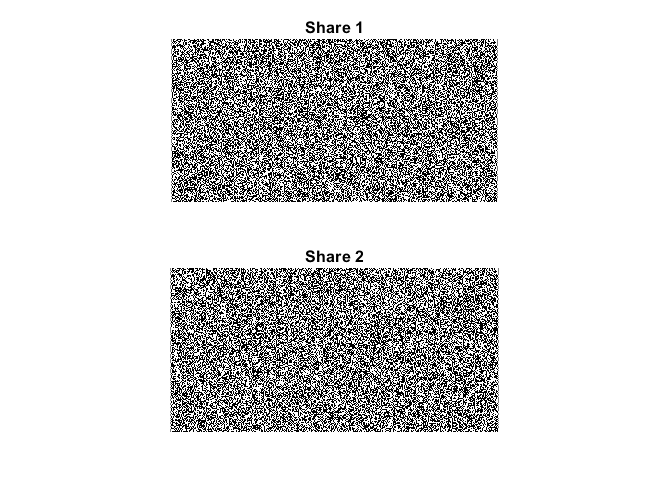

s = size(recImg);
share2 = reshape(recImg,[s(2),s(1)]);


figure;subplot(211);imshow(share1);title('Share 1'); 
       subplot(212);imshow(share2);title('Share 2');

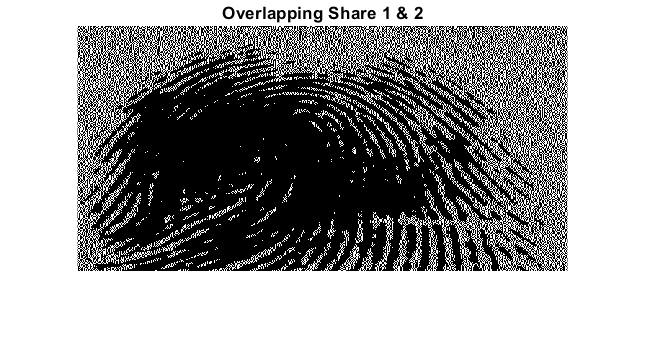

% Decrypting the shares
tic
share12 = bitor(share1, share2);
share12 = ~share12;


s = [300 , 300];
shareop = zeros(s);
for i = 1:s(1)
for j = 1:s(2)
    a = share12(i,(2*j-1):(2*j));
    shareop(i,j) = max(a);
end
end
t2 = toc;
figure;imshow(share12);title('Overlapping Share 1 & 2');


disp("VCS Decryption")

VCS Decryption


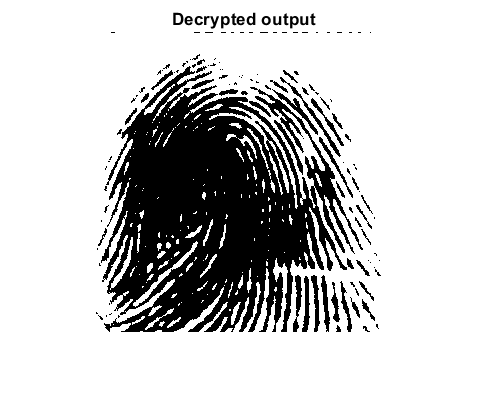


figure;imshow(shareop);title('Decrypted output');

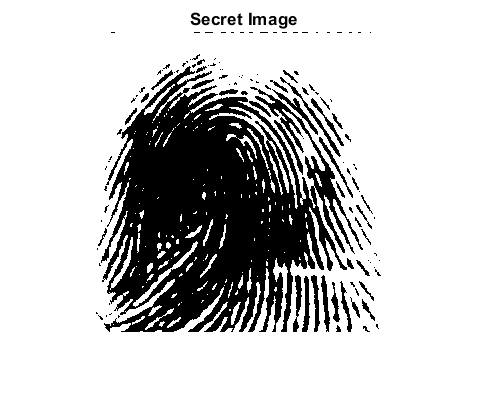


inImg = imread('102_3.tif');
inImg = imbinarize(inImg);
figure;imshow(inImg);title('Secret Image');

tic
thresh = xor(shareop,inImg);
thresh = sum(sum(thresh));
if thresh < 0.1*size(inImg,1)*size(inImg,2)
    disp("Authenticated.")
end

Authenticated.


t4 = toc;


t1 = 0.0238

t2 = 0.1242

t4 = 0.0171

time  = t1 + t2 + t4;
disp("Time taken for Decryption")

Time taken for Decryption


disp(time)

    0.1651

